# Tarea: Navegación por Campo Potencial con Robot Pioneer P3DX

Autores: Andrés Sebastian Serna Montaño

Joan Pinilla

## Paso 1: Modelo cinemático del robot Pioneer P3DX

El Pioneer P3DX es un robot diferencial.

Cinemática: 


$$\frac{\textrm{dx}}{\textrm{dt}}=v*\textrm{Cos}\left(\theta \right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=v*\textrm{Sin}\left(\theta \right)$$



$$\frac{d\theta }{\textrm{dt}}=w$$


## Paso 2.1: Calcular el radio R del círculo que incluye al robot

Dimensiones aproximadas del Pioneer P3DX:

Ancho: 0.381 m

Largo: 0.455 m

Radio de inclusión R:

R = sqrt((0.381)^2 + (0.455)^2)/2;
k = 10 * R; % Factor de escala para el mapa

## Paso 2.2: Generar mapa con obstáculos usando arena2025

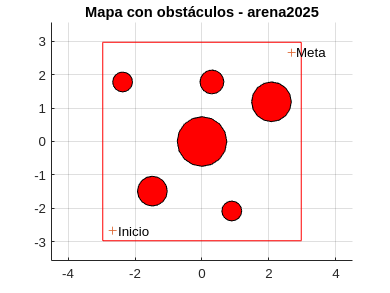

clf
figure(1); hold on
plot(k*[-1 1 1 -1 -1], k*[-1 -1 1 1 -1], 'r')
CC = k*0.1 * [3 -7;-5 -5;0 0;-8 6;1 6;7 4]; % centros de obstáculos
RC = k*0.1 * [1 1.5 2.5 1 1.2 2];          % radios de obstáculos
t = 0:pi/8:2*pi;
for i = 1:length(RC)
    patch(CC(i,1)+RC(i)*sin(t), CC(i,2)+RC(i)*cos(t), 'r')
end
plot(k*[-.9, .9], k*[-.9, .9], '+')
text(-k*.85, -k*.9, 'Inicio')
text(k*.95, k*.9, 'Meta')
axis(k*[-1.2 1.2 -1.2 1.2]); axis equal; grid on
title('Mapa con obstáculos - arena2025')


nombreMapa = 'Mapa_Pioneer296';

## Paso 2.3: Campo de repulsión con función tangente sigmoidal

% f(d) = 1 / (1 + exp(-a*(d - d0)))


## Paso 3: Navegación por Campo Potencial

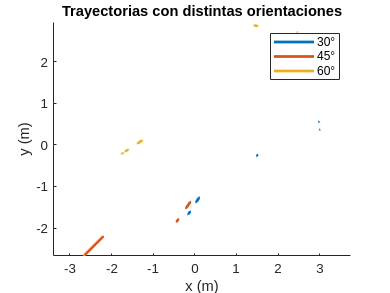

x_hist =    -2.6705   -2.6455   -2.6183   -2.5893   -2.5590   -2.5275   -2.4952   -2.4622   -2.4287   -2.3948   -2.3605   -2.3259   -2.2910   -2.2561   -2.2209   -2.1857   -2.1503   -2.1423   -2.1590   -2.1916   -2.2339   -2.2812   -2.3300   -2.3796   -2.4296   -2.4789   -2.5258   -2.5617   -2.5844   -2.5946   -2.5941   -2.5851   -2.5694   -2.5484   -2.5234   -2.4953   -2.4647   -2.4540   -2.4610   -2.4815   -2.5118   -2.5487   -2.5901   -2.6181   -2.6323   -2.6343   -2.6263   -2.6106   -2.5888   -2.5626
   -2.6705   -2.6272   -2.5853   -2.5445   -2.5048   -2.4660   -2.4278   -2.3902   -2.3531   -2.3164   -2.2800   -2.2439   -2.2080   -2.1723   -2.1368   -2.1013   -2.0659   -2.0166   -1.9695   -1.9315   -1.9048   -1.8886   -1.8778   -1.8713   -1.8728   -1.8807   -1.8633   -1.8286   -1.7840   -1.7351   -1.6851   -1.6359   -1.5884   -1.5430   -1.4998   -1.4584   -1.4189   -1.3700   -1.3205   -1.2749   -1.2351   -1.2014   -1.1734   -1.1320   -1.0840   -1.0341   -0.9847   -0.9372   -0.8922

% Parámetros iniciales
k_atr = 1;        % Atracción
k_rep = 100;      % Repulsión
a_sig = 10;       % Pendiente sigmoide
d0 = 0.5;         % Distancia de activación repulsión

% Puntos de inicio y meta
start = [-k*0.9; -k*0.9];
goal = [k*0.9; k*0.9];

[X, Y] = meshgrid(-k:0.1:k, -k:0.1:k);
U = zeros(size(X));

% Campo atractivo
U_atr = 0.5 * k_atr * ((X - goal(1)).^2 + (Y - goal(2)).^2);
U = U + U_atr;

% Campo repulsivo con sigmoide
for i = 1:length(RC)
    dx = X - CC(i,1);
    dy = Y - CC(i,2);
    dist = sqrt(dx.^2 + dy.^2) - RC(i);
    f_rep = k_rep * (1 - (1 ./ (1 + exp(-a_sig*(dist - d0)))));
    f_rep(dist > d0) = 0; % sin repulsión si está lejos
    U = U + f_rep;
end

% Gradiente del campo
[Fx, Fy] = gradient(-U);

%% Simulación del movimiento del robot para orientaciones 30°, 45°, 60°
orientaciones = [30, 45, 60] * pi/180;

for j = 1:length(orientaciones)
    x = [start; orientaciones(j)];
    dt = 0.1;
    x_hist = x;
    for i = 1:300
        % Posición actual del robot
        px = x(1);
        py = x(2);
        
        % Buscar el gradiente más cercano
        ix = round((px + k)/0.1)+1;
        iy = round((py + k)/0.1)+1;
        if ix < 1 || iy < 1 || ix > size(Fx,1) || iy > size(Fx,2)
            break;
        end
        
        grad = [Fx(iy,ix); Fy(iy,ix)];
        
        % Dirección deseada
        theta_d = atan2(grad(2), grad(1));
        dtheta = wrapToPi(theta_d - x(3));

        % Control proporcional simple
        v = 0.5;
        w = 2*dtheta;

        % Simular movimiento
        x = x + dt * modeloP3DX(0, x, [v; w]);
        x_hist(:,end+1) = x;
        
        % Criterio de parada
        if norm(x(1:2) - goal) < 0.2
            break;
        end
    end

    % Graficar trayectoria
    figure(3); hold on
    plot(x_hist(1,:), x_hist(2,:), 'LineWidth', 2)
    title('Trayectorias con distintas orientaciones')
    xlabel('x (m)'); ylabel('y (m)');
end

legend('30°', '45°', '60°')
axis equal

## Paso 3.4: Tabla de parámetros usados

fprintf('\nParametros usados:\n')


Parametros usados:


fprintf('k_atr = %.2f\n', k_atr)

k_atr = 1.00


fprintf('k_rep = %.2f\n', k_rep)

k_rep = 100.00


fprintf('a_sig = %.2f\n', a_sig)

a_sig = 10.00


fprintf('d0 = %.2f\n', d0)

d0 = 0.50


## Paso 4: Visualización del Gradiente del Campo Potencial

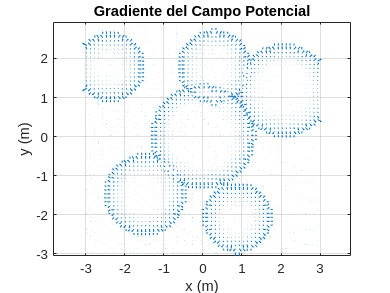

figure(4);
quiver(X, Y, Fx, Fy)
title('Gradiente del Campo Potencial')
xlabel('x (m)'); ylabel('y (m)');
axis equal; grid on

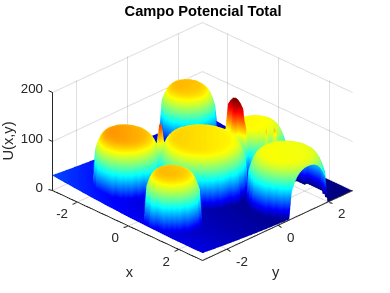


figure(5);
surf(X, Y, U);
title('Campo Potencial Total');
xlabel('x'); ylabel('y'); zlabel('U(x,y)');
shading interp; colormap jet; view(45, 45);